## Direct Fight Between Humans and Aliens

### Aliens are able to adapt to Earth

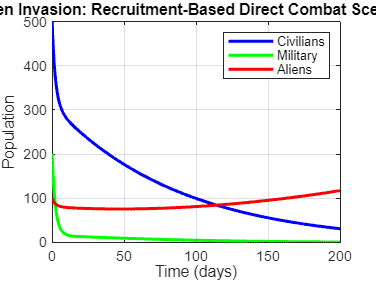

% Parameters for the model
rH = 0.03;      % Human civilian population growth rate
k = 0.02;       % Recruitment rate from civilians to military
rA = 0.005;     % Alien population growth rate
alpha = 0.0005; % Alien death rate due to human military
beta = 0.005; % Human military death rate due to aliens
gamma = 0.00001;% Alien death rate due to environmental adaptation
lambda = 0.00002; % Alien death rate due to non-military humans
delta = 0.00001;  % Civilians killed by aliens
C = 0.0005;       % Probability factor of civilians killing aliens

% Initial conditions
H0 = 500;      % Initial human civilian population
M0 = 200;      % Initial human military population
A0 = 100;      % Initial alien population

% Time span
tspan = [0, 200]; % Extend time for better analysis

% ODE function
function dYdt = combat_odes(t, Y, rH, k, rA, alpha, beta, gamma, lambda, delta, C)
    H = Y(1);  % Civilians
    M = Y(2);  % Military
    A = Y(3);  % Aliens

    % Military recruitment (cannot exceed civilians)
    recruitment = k * H;
    if recruitment + M > H
        recruitment = H - M;
    end

    % Interaction terms for debugging
    combat_human_loss = beta * M * A;
    combat_alien_loss = alpha * M * A;
    civilian_alien_loss = delta * H * A;
    environment_loss = gamma * A;

    %fprintf('t=%.2f | H=%.2f, M=%.2f, A=%.2f | H_loss=%.2f, A_loss=%.2f\n', ...
    %    t, H, M, A, combat_human_loss, combat_alien_loss);

    % Differential equations
    dHdt = rH * H - combat_human_loss - civilian_alien_loss - recruitment; % Civilians grow but lose to aliens, combat, and recruitment
    dMdt = recruitment - combat_human_loss;                               % Military recruits but loses in combat
    dAdt = rA * A - combat_alien_loss - environment_loss - C * lambda * H; % Aliens lose to military, environment, and civilians

    dYdt = [dHdt; dMdt; dAdt];
end

% Solving the ODEs
Y0 = [H0; M0; A0];
[t, Y] = ode45(@(t, Y) combat_odes(t, Y, rH, k, rA, alpha, beta, gamma, lambda, delta, C), tspan, Y0);

% Plotting results
figure;
plot(t, Y(:, 1), 'b', 'LineWidth', 2); hold on;
plot(t, Y(:, 2), 'g', 'LineWidth', 2);
plot(t, Y(:, 3), 'r', 'LineWidth', 2);
xlabel('Time (days)');
ylabel('Population');
legend('Civilians', 'Military', 'Aliens');
title('Alien Invasion: Recruitment-Based Direct Combat Scenario');
grid on;

### Alien Not able to Adapt to Earth

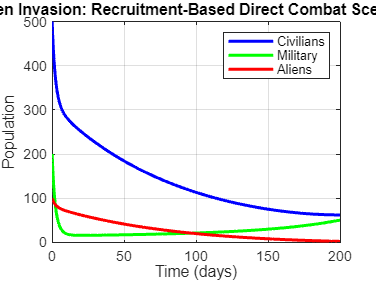

% Parameters for the model
rH = 0.03;      % Human civilian population growth rate
k = 0.02;       % Recruitment rate from civilians to military
rA = 0.005;     % Alien population growth rate
alpha = 0.0005; % Alien death rate due to human military
beta = 0.005; % Human military death rate due to aliens
gamma = 0.01;% Alien death rate due to environmental adaptation
lambda = 0.00002; % Alien death rate due to non-military humans
delta = 0.00001;  % Civilians killed by aliens
C = 0.0005;       % Probability factor of civilians killing aliens

% Initial conditions
H0 = 500;      % Initial human civilian population
M0 = 200;      % Initial human military population
A0 = 100;      % Initial alien population

% Time span
tspan = [0, 200]; % Extend time for better analysis

% ODE function
function dYdt = combat_odes_2(t, Y, rH, k, rA, alpha, beta, gamma, lambda, delta, C)
    H = Y(1);  % Civilians
    M = Y(2);  % Military
    A = Y(3);  % Aliens

    % Military recruitment (cannot exceed civilians)
    recruitment = k * H;
    if A == 0
        recruitment = 0;
    end
    if recruitment + M > H
        recruitment = H - M;
    end

    % Interaction terms for debugging
    combat_human_loss = beta * M * A;
    combat_alien_loss = alpha * M * A;
    civilian_alien_loss = delta * H * A;
    environment_loss = gamma * A;

    %fprintf('t=%.2f | H=%.2f, M=%.2f, A=%.2f | H_loss=%.2f, A_loss=%.2f\n', ...
    %    t, H, M, A, combat_human_loss, combat_alien_loss);

    % Differential equations
    dHdt = rH * H - combat_human_loss - civilian_alien_loss - recruitment; % Civilians grow but lose to aliens, combat, and recruitment
    dMdt = recruitment - combat_human_loss;                               % Military recruits but loses in combat
    dAdt = rA * A - combat_alien_loss - environment_loss - C * lambda * H; % Aliens lose to military, environment, and civilians

    dYdt = [dHdt; dMdt; dAdt];
end

% Solving the ODEs
Y0 = [H0; M0; A0];
[t, Y] = ode45(@(t, Y) combat_odes_2(t, Y, rH, k, rA, alpha, beta, gamma, lambda, delta, C), tspan, Y0);

% Plotting results
figure;
plot(t, Y(:, 1), 'b', 'LineWidth', 2); hold on;
plot(t, Y(:, 2), 'g', 'LineWidth', 2);
plot(t, Y(:, 3), 'r', 'LineWidth', 2);
xlabel('Time (days)');
ylabel('Population');
legend('Civilians', 'Military', 'Aliens');
title('Alien Invasion: Recruitment-Based Direct Combat Scenario');
grid on;

## Alien-Induced Disease Dynamics

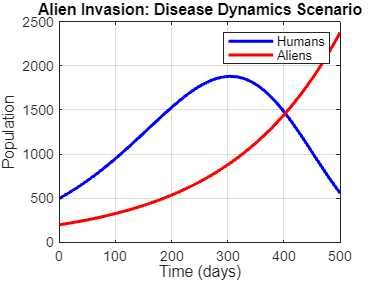

% Parameters for the model
rH = 0.03;       % Human population growth rate (birth rate)
rA = 0.005;      % Alien population growth rate
gamma = 0.00001; % Alien death rate due to environmental adaptation
lambda = 0.00002;% Alien death rate due to human resistance
deltaD = 0.00001;% Disease-induced human mortality rate
deltaF = 0.5;    % Disease-induced fertility reduction factor
cropImpact = 0.4;% Reduction in effective growth rate due to alien crop impact

% Initial conditions
H0 = 500;        % Initial human civilian population
A0 = 200;        % Initial alien population

% Time span
tspan = [0, 500];

% ODE function
function dYdt = disease_odes(t, Y, rH, rA, gamma, lambda, deltaD, deltaF, cropImpact)
    H = Y(1);  % Civilians
    A = Y(2);  % Aliens

    % Effective human population growth considering disease and crop impact
    effective_rH = rH * (1 - deltaF) * (1 - cropImpact);
    if effective_rH < 0
        effective_rH = 0; % Prevent negative growth rate
    end

    % Differential equations
    dHdt = effective_rH * H - deltaD * H * A;       % Human growth with fertility reduction and disease impact
    dAdt = rA * A - gamma * A - lambda * H;         % Alien growth with environmental and human resistance losses

    dYdt = [dHdt; dAdt];
end

% Solving the ODEs
Y0 = [H0; A0];
[t, Y] = ode45(@(t, Y) disease_odes(t, Y, rH, rA, gamma, lambda, deltaD, deltaF, cropImpact), tspan, Y0);

% Plotting results
figure;
plot(t, Y(:, 1), 'b', 'LineWidth', 2); hold on;
plot(t, Y(:, 2), 'r', 'LineWidth', 2);
xlabel('Time (days)');
ylabel('Population');
legend('Humans', 'Aliens');
title('Alien Invasion: Disease Dynamics Scenario');
grid on;

## Aleins Brainwashing Humans

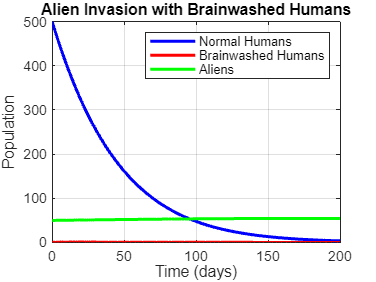

% Parameters
rH = 0.03;        % Human population growth rate (birth rate)
gamma = 0.00001;  % Alien death rate due to environmental adaptation
lambda = 0.00002; % Alien death rate due to human resistance
beta_n = 0.001; % Death rate of normal humans in combat with aliens
beta_b = 0.002; % Death rate of brainwashed humans in combat with aliens
alpha_n = 0.0015; % Death rate of brainwashed humans due to normal humans
alpha_b = 0.0001;  % Death rate of normal humans due to brainwashed humans
conversion_rate = 0.00003; % Alien-induced brainwashing conversion rate
slave_effect = 0.001;      % Reduction in alien death rate due to brainwashed humans

% Initial conditions
Hn0 = 500;    % Initial normal human population (500 humans)
Hb0 = 0;      % Initial brainwashed human population (0 initially)
A0 = 50;      % Initial alien population (50 aliens)

% Time span
tspan = [0, 200];  % Time span for simulation (500 days)

% ODE function
function dYdt = brainwashed_odes(t, Y, rH, gamma, lambda, beta_n, beta_b, alpha_n, alpha_b, conversion_rate, slave_effect)
    Hn = Y(1); % Normal humans
    Hb = Y(2); % Brainwashed humans
    A = Y(3);  % Aliens

    % Differential equations
    dHndt = rH * Hn - conversion_rate * Hn * A - beta_n * Hn * A - alpha_b * Hn * Hb; % Normal humans
    dHbdt = conversion_rate * Hn * A - beta_b * Hb * A - alpha_n * Hn * Hb; % Brainwashed humans
    dAdt = -gamma * A + slave_effect * Hb * A - lambda * A; % Aliens, with effect of brainwashed humans

    dYdt = [dHndt; dHbdt; dAdt];
end

% Initial population vector
Y0 = [Hn0; Hb0; A0];

% Solving the ODEs
[t, Y] = ode45(@(t, Y) brainwashed_odes(t, Y, rH, gamma, lambda, beta_n, beta_b, alpha_n, alpha_b, conversion_rate, slave_effect), tspan, Y0);

% Plotting results
figure;
plot(t, Y(:, 1), 'b', 'LineWidth', 2); hold on;  % Normal humans
plot(t, Y(:, 2), 'r', 'LineWidth', 2);  % Brainwashed humans
plot(t, Y(:, 3), 'g', 'LineWidth', 2);  % Aliens
xlabel('Time (days)');
ylabel('Population');
legend('Normal Humans', 'Brainwashed Humans', 'Aliens');
title('Alien Invasion with Brainwashed Humans');
grid on;

## Co-existing

### Hybrids Exist

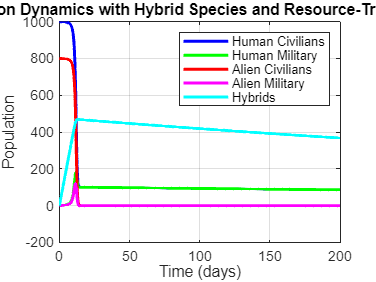

% Parameters for the model
r_H = 0.0003;     % Human civilian growth rate
r_A = 0.0001;     % Alien civilian growth rate
r_Hyb = 0.0002;   % Hybrid civilian growth rate
k_H_peace = 0.001; % Human military recruitment rate during peace
k_H_war = 0.02;    % Human military recruitment rate during war
k_A_peace = 0.001; % Alien military recruitment rate during peace
k_A_war = 0.02;    % Alien military recruitment rate during war
alpha = 0.0005;    % Alien military death rate due to human military
beta = 0.0005;     % Human military death rate due to alien military
gamma_H = 0.002;   % Human death rate from resource scarcity
gamma_A = 0.002;   % Alien death rate from resource scarcity
gamma_Hyb = 0.0015; % Hybrid death rate from resource scarcity
sigma = 0.05;      % Resource consumption rate proportional to total population
theta = 0.05;      % Resource replenishment rate
R_threshold = 500; % Resource threshold for scarcity (triggers war)
max_population = 3000; % Maximum carrying capacity of the environment
hybrid_creation_rate = 0.00005; % Rate of hybrid creation from human-alien interaction

% Initial conditions
H0 = 1000;      % Initial human civilian population
M_H0 = 0;       % Initial human military population
A0 = 800;       % Initial alien civilian population
M_A0 = 0;       % Initial alien military population
Hyb0 = 0;       % Initial hybrid population
R0 = 1000;      % Initial resources
war_state0 = 0; % Peace at the start (0 = peace, 1 = war)

% Time span
tspan = [0, 200];

% ODE function with hybrid species and war logic
function dYdt = population_dynamics(t, Y, r_H, r_A, r_Hyb, k_H_peace, k_H_war, k_A_peace, k_A_war, alpha, beta, gamma_H, gamma_A, gamma_Hyb, sigma, theta, R_threshold, max_population, hybrid_creation_rate)
    H = max(Y(1), 0);   % Human civilians
    M_H = max(Y(2), 0); % Human military
    A = max(Y(3), 0);   % Alien civilians
    M_A = max(Y(4), 0); % Alien military
    Hyb = max(Y(5), 0); % Hybrid population
    R = max(Y(6), 0);   % Resources
    war_state = Y(7);   % War state (0 = peace, 1 = war)

    % Total population and resource dynamics
    total_population = H + M_H + A + M_A + Hyb;
    R_depletion = sigma * total_population; % Resource consumption rate proportional to total population
    R_replenishment = theta * R * (1 - total_population / max_population); % Replenishment slows as population nears capacity
    dRdt = R_replenishment - R_depletion;

    % Determine war state based on resource scarcity and population pressure
    if war_state == 0 && (R < R_threshold || total_population > max_population)
        war_state = 1; % War starts
    elseif war_state == 1 && R >= R_threshold && total_population <= max_population
        war_state = 0; % Peace returns
    end

    % Recruitment rates based on war state
    k_H = war_state * (k_H_war - k_H_peace) + k_H_peace;
    k_A = war_state * (k_A_war - k_A_peace) + k_A_peace;

    % Recruitment logic (cannot exceed civilian populations)
    recruitment_H = min(k_H * H, H - M_H);
    recruitment_A = min(k_A * A, A - M_A);

    % Hybrid creation (dependent on human-alien interaction)
    hybrid_creation = hybrid_creation_rate * (H + M_H) * (A + M_A);

    % Scarcity-induced death rates
    death_H_scarcity = gamma_H * H * max(0, R_threshold - R) / R_threshold;
    death_A_scarcity = gamma_A * A * max(0, R_threshold - R) / R_threshold;
    death_Hyb_scarcity = gamma_Hyb * Hyb * max(0, R_threshold - R) / R_threshold;

    % Combat losses (only during war)
    combat_H_loss = war_state * beta * M_H * M_A; % Humans killed by aliens
    combat_A_loss = war_state * alpha * M_H * M_A; % Aliens killed by humans

    % Population dynamics
    dHdt = r_H * H - recruitment_H - death_H_scarcity - combat_H_loss; % Humans
    dMHdt = recruitment_H - combat_H_loss;                            % Human military
    dAdt = r_A * A - recruitment_A - death_A_scarcity - combat_A_loss; % Aliens
    dMAdt = recruitment_A - combat_A_loss;                            % Alien military
    dHybdt = r_Hyb * Hyb + hybrid_creation - death_Hyb_scarcity;       % Hybrids

    % Output derivatives
    dYdt = [dHdt; dMHdt; dAdt; dMAdt; dHybdt; dRdt; war_state];
end

% External simulation loop
dt = 0.1; % Time step
time = 0:dt:tspan(2);
Y = zeros(length(time), 7);
Y(1, :) = [H0, M_H0, A0, M_A0, Hyb0, R0, war_state0];

% Solve ODEs using manual simulation
for i = 1:length(time)-1
    dYdt = population_dynamics(time(i), Y(i, :)', r_H, r_A, r_Hyb, k_H_peace, k_H_war, k_A_peace, k_A_war, alpha, beta, gamma_H, gamma_A, gamma_Hyb, sigma, theta, R_threshold, max_population, hybrid_creation_rate);
    Y(i+1, :) = Y(i, :) + dYdt' * dt;
end

% Plot populations
figure;
plot(time, Y(:, 1), 'b', 'LineWidth', 2); hold on;
plot(time, Y(:, 2), 'g', 'LineWidth', 2);
plot(time, Y(:, 3), 'r', 'LineWidth', 2);
plot(time, Y(:, 4), 'm', 'LineWidth', 2);
plot(time, Y(:, 5), 'c', 'LineWidth', 2);
xlabel('Time (days)');
ylabel('Population');
legend('Human Civilians', 'Human Military', 'Alien Civilians', 'Alien Military', 'Hybrids');
title('Population Dynamics with Hybrid Species and Resource-Triggered War');
grid on;

### No interbreeding among humans and aliens

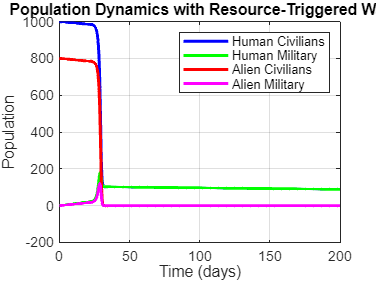

% Parameters for the model
r_H = 0.0003;     % Human civilian growth rate
r_A = 0.0001;     % Alien civilian growth rate
k_H_peace = 0.001; % Human military recruitment rate during peace
k_H_war = 0.02;    % Human military recruitment rate during war
k_A_peace = 0.001; % Alien military recruitment rate during peace
k_A_war = 0.02;    % Alien military recruitment rate during war
alpha = 0.0005;    % Alien military death rate due to human military
beta = 0.0005;     % Human military death rate due to alien military
gamma_H = 0.002;   % Human death rate from resource scarcity
gamma_A = 0.002;   % Alien death rate from resource scarcity
sigma = 0.05;      % Resource consumption rate proportional to total population
theta = 0.05;      % Resource replenishment rate
R_threshold = 500; % Resource threshold for scarcity (triggers war)
max_population = 3000; % Maximum carrying capacity of the environment

% Initial conditions
H0 = 1000;      % Initial human civilian population
M_H0 = 0;       % Initial human military population
A0 = 800;       % Initial alien civilian population
M_A0 = 0;       % Initial alien military population
R0 = 2000;      % Initial resources
war_state0 = 0; % Peace at the start (0 = peace, 1 = war)

% Time span
tspan = [0, 200];

% ODE function with war logic
function dYdt = population_dynamics_2(t, Y, r_H, r_A, k_H_peace, k_H_war, k_A_peace, k_A_war, alpha, beta, gamma_H, gamma_A, sigma, theta, R_threshold, max_population)
    H = max(Y(1), 0);   % Human civilians
    M_H = max(Y(2), 0); % Human military
    A = max(Y(3), 0);   % Alien civilians
    M_A = max(Y(4), 0); % Alien military
    R = max(Y(5), 0);   % Resources
    war_state = Y(6);   % War state (0 = peace, 1 = war)

    % Total population and resource dynamics
    total_population = H + M_H + A + M_A;
    R_depletion = sigma * total_population; % Resource consumption rate proportional to total population
    R_replenishment = theta * R * (1 - total_population / max_population); % Replenishment slows as population nears capacity
    dRdt = R_replenishment - R_depletion;

    % Determine war state based on resource scarcity and population pressure
    if war_state == 0 && (R < R_threshold || total_population > max_population)
        war_state = 1; % War starts
    elseif war_state == 1 && R >= R_threshold && total_population <= max_population
        war_state = 0; % Peace returns
    end

    % Recruitment rates based on war state
    k_H = war_state * (k_H_war - k_H_peace) + k_H_peace;
    k_A = war_state * (k_A_war - k_A_peace) + k_A_peace;

    % Recruitment logic (cannot exceed civilian populations)
    recruitment_H = min(k_H * H, H - M_H);
    recruitment_A = min(k_A * A, A - M_A);

    % Scarcity-induced death rates
    death_H_scarcity = gamma_H * H * max(0, R_threshold - R) / R_threshold;
    death_A_scarcity = gamma_A * A * max(0, R_threshold - R) / R_threshold;

    % Combat losses (only during war)
    combat_H_loss = war_state * beta * M_H * M_A; % Humans killed by aliens
    combat_A_loss = war_state * alpha * M_H * M_A; % Aliens killed by humans

    % Population dynamics
    dHdt = r_H * H - recruitment_H - death_H_scarcity - combat_H_loss; % Humans
    dMHdt = recruitment_H - combat_H_loss;                            % Human military
    dAdt = r_A * A - recruitment_A - death_A_scarcity - combat_A_loss; % Aliens
    dMAdt = recruitment_A - combat_A_loss;                            % Alien military

    % Output derivatives
    dYdt = [dHdt; dMHdt; dAdt; dMAdt; dRdt; war_state];
end

% External simulation loop
dt = 0.1; % Time step
time = 0:dt:tspan(2);
Y = zeros(length(time), 6);
Y(1, :) = [H0, M_H0, A0, M_A0, R0, war_state0];

% Solve ODEs using manual simulation
for i = 1:length(time)-1
    dYdt = population_dynamics_2(time(i), Y(i, :)', r_H, r_A, k_H_peace, k_H_war, k_A_peace, k_A_war, alpha, beta, gamma_H, gamma_A, sigma, theta, R_threshold, max_population);
    Y(i+1, :) = Y(i, :) + dYdt' * dt;
end

% Plot populations
figure;
plot(time, Y(:, 1), 'b', 'LineWidth', 2); hold on;
plot(time, Y(:, 2), 'g', 'LineWidth', 2);
plot(time, Y(:, 3), 'r', 'LineWidth', 2);
plot(time, Y(:, 4), 'm', 'LineWidth', 2);
xlabel('Time (days)');
ylabel('Population');
legend('Human Civilians', 'Human Military', 'Alien Civilians', 'Alien Military');
title('Population Dynamics with Resource-Triggered War');
grid on;